P = [
    -0.0250  -27.6981  -46.2239    0.1846   43.1597   53.9402   81.6133   89.3586   69.5267   42.9501   23.6954   -0.0250;
   -0.1553   -1.4497   -2.3601   -5.4546   -4.6550   -4.2150   -2.9206   -2.4502   -1.0378    0.6443    0.3338   -0.1553
];
N_verts = size(P, 2);

N_plot_pts = 5;
thetas = linspace(0, 2*pi, N_plot_pts+1);
thetas = thetas(1:end-1);

center = mean(P, 2);
[A, b] = vert2lcon(P');

pts_optim = zeros(2, N_plot_pts);
costs = zeros(1, N_plot_pts);
w_optims = zeros(N_verts, N_plot_pts);
abcs = zeros(3, N_plot_pts);
for i = 1 : length(thetas)
    % Find the point on the boundary of P that intersects with the ray from
    % theta.
    theta_i = thetas(i);

    c = center;
    line_abc_form = [sin(theta_i), -cos(theta_i), -(sin(theta_i)* c(1) + cos(theta_i)*c(2))];
    abcs(:, i) = line_abc_form;

    w_0 = zeros(N_verts, 1);
    w_0(1) = 1;
    lb = zeros(N_verts, 1);

    f_nonlcon = @(pt) nonl_edge_constraint(pt, A, b);

    f_cost = @(w) -norm(P*w - center);

    A = ones(1, N_verts);
    b = 1;

    P_homogenous = [P; ones(1, N_verts)];
    A_eq = line_abc_form * P_homogenous;
    b_eq = 0;

    lb = zeros(1, N_verts);
    [wt_optim, costs(i)] = fmincon(f_cost, w_0, A, b, A_eq, b_eq, lb);
    pt_optim = P * wt_optim;
    pts_optim(:, i) = pt_optim;
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

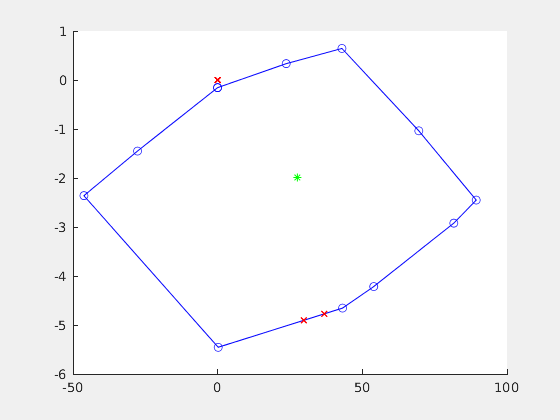

figure("visible", true)
hold on
plot(P(1, :), P(2, :), "bo-");
plot(pts_optim(1, :), pts_optim(2, :), 'rx');
plot(center(1), center(2), 'g*')

% Alternatively try to do it with the interpolation method
s = 0;
s_of_verts = zeros(1, N_verts);
for i = 2 : N_verts
    p_last = P(:, i-1);
    p_now = P(:, i);
    
    dist_i = norm(p_now - p_last);
    s = s + dist_i;
    s_of_verts(i) = s;
end


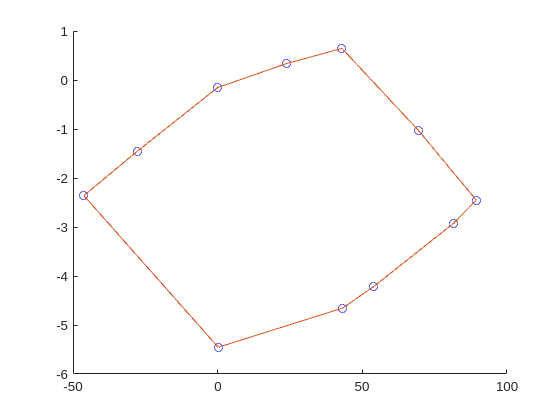

s_of_verts_normed = s_of_verts / s_of_verts(end);
query_pts = linspace(0, 1, N_plot_pts);

query_pts_all = union(query_pts, s_of_verts_normed);

px_interp = interp1(s_of_verts_normed, P(1, :), query_pts);
py_interp = interp1(s_of_verts_normed, P(2, :), query_pts);

Ps_interp = [px_interp; py_interp];
figure()
hold on
plot(P(1, :), P(2, :), "bo-");
plot(Ps_interp(1, :), Ps_interp(2, :))

function cost = cost_func(pt, center, theta_target)
    dx = pt - center;
    theta_real = atan2(dx(2), dx(1));

    cost = abs(theta_real - theta_target);
end

function dist = dist_to_line(pt, abc)
    pt_homogenous = [pt; 1];
    
    dist = abs(dot(pt_homogenous, abc)) / sqrt(abc(1)^2 + abc(2)^2);
end

function [ineq_cost, eq_cost]  = nonl_edge_constraint(pts, A, b)
    %on_edge = abs(A*pts - b) < 1e-6;
    ineq_cost = 0;
    eq_cost = prod(A*pts - b);
end